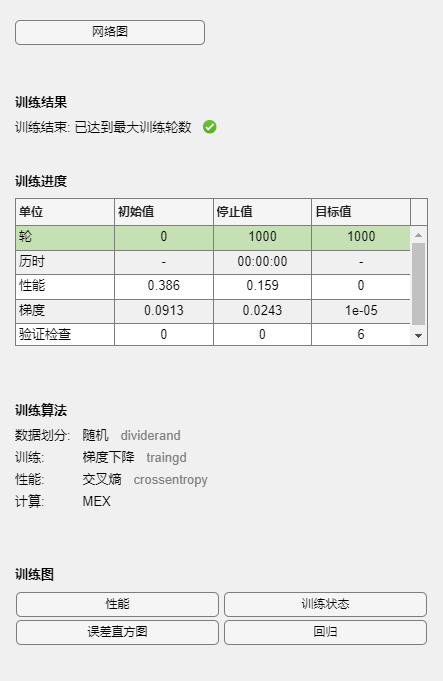

close all;
clear;clc;
load fisheriris;
for i=1:size(meas,2)
    t = meas(:,i);
    t = (t-min(t(:)))./(max(t(:))-min(t(:)));
    meas(:,i) = t;
end
meas = meas';

% Encode the label with one-hot vector
str = unique(species);
[found,idx] = ismember(species,str);
species_vec = full(ind2vec(idx'));

% Create an MLP
net = feedforwardnet(2,'traingd');

% Configure the net
net.divideParam.trainRatio = 1; % training set
net.divideParam.valRatio = 0; % validation set
net.divideParam.testRatio = 0; % test set
net.inputs{1}.processFcns = {}; % modify the process function for inputs
net.outputs{2}.processFcns = {}; % modify the process function for outputs
% net.layers{1}.transferFcn = 'logsig'; % logistic function
% net.layers{1}.transferFcn = 'tansig'; % Tanh
net.layers{1}.transferFcn = 'poslin'; % ReLU
net.layers{2}.transferFcn = 'softmax'; % the transfer function for the second layer
net.performFcn = 'crossentropy'; % the loss function
net.trainParam.lr = 0.1; % learning rate

% Divide the dataset into training set and test set
cvo = cvpartition(species,'k',2);
tridx = cvo.training(1);
teidx = cvo.test(1);
training_x = meas(:,tridx);
training_y = species_vec(:,tridx);
test_x = meas(:,teidx);
test_y = species_vec(:,teidx);

% Train the net
net = train(net, training_x, training_y);


y_hat = sim(net,test_x);

accuracy = 0;
for i=1:min(size(y_hat))
    accuracy = accuracy + sum(test_y(i,:) == round(y_hat(i,:)))/max(size(y_hat))*100;
end

accuracy = accuracy/3;

disp(accuracy);

   96.4444




AUC = 0;
for i=1:min(size(y_hat))
    [X,Y,T,A] = perfcurve(test_y(i,:), y_hat(i,:), 1);
    AUC = AUC + A;
end

AUC = AUC/3;

disp(AUC);

    0.9925

